clearvars
close all
clc

%% define variables and likelihood function

syms y1 y2 y3 T fD v l eta a b c K sp

% loglike = (y - 2*pi*T*(fD+(v/l)*(cos(eta - a) - cos(eta))))^2/(2*sp);

loglike = (y1 - f1(fD, v, eta, T, l, a))^2 / (2*sp) + (y2 - fm(v, eta, T, l, b))^2 / (2*sp) + (y3 - fm(v, eta, T, l, c))^2 / (2*sp);

%% compute all the 1st and second derivatives

dLdfD = diff(loglike, fD);
dLdeta = diff(loglike, eta);
dLdv = diff(loglike, v);

dLdfD2 = diff(loglike, fD, 2);
dLdeta2 = diff(loglike, eta, 2);
dLdv2 = diff(loglike, v, 2);

dLdfDdeta = diff(dLdfD, eta);
dLdfDdv = diff(dLdfD, v);
dLdvdeta = diff(dLdv, eta);
% % 
% pretty(dLdfD2)
% pretty(dLdeta2)
% pretty(dLdv2)
% pretty(dLdfDdeta)
% pretty(dLdfDdv)
% pretty(dLdvdeta)

%% define Fisher information matrix

Ey1 = f1(fD, v, eta, T, l, a);
Ey2 = fm(v, eta, T, l, b);
Ey3 = fm(v, eta, T, l, c);

A = -dLdfD2;
B = -dLdfDdeta;
C = -dLdfDdv;

E = -subs(dLdeta2, [y1, y2, y3], [Ey1, Ey2, Ey3]);  % here y remains and we take expectation
D = -subs(dLdvdeta, [y1, y2, y3], [Ey1, Ey2, Ey3]); % here y remains and we take expectation
F = -dLdv2;


% pretty(A)
% pretty(E)
% pretty(F)
% pretty(B)
% pretty(C)
% pretty(D)

FI = [[A, B, C]; [B, E, D]; [C, D, F]];

invFI = inv(FI);


pretty(simplify(invFI(1,1)))

  sp (cos(2 a) 2 + cos(2 b) 2 + cos(2 c) 2 - cos(2 a - b) 2 + cos(2 a - 2 b) - cos(2 a - c) 2 + cos(2 a - 2 c) - cos(2 b - c) 2 + cos(2 b - 2 c) - 2 cos(a + b) - 2 cos(a + c) - 2 cos(b + c) + 4 cos(a) + 4 cos(b) + 4 cos(c) + 2 cos(a - b) - cos(a - 2 b) 2 + 2 cos(a - c) - cos(a - 2 c) 2 + 2 cos(b - c) - cos(b - 2 c) 2 - 9)
- ---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                             2   2
                                                                                                                                         16 T  pi  (cos(b) - 1) (cos(c) - 1) (cos(b - c) - 1)





% pretty(simplify(invFI(2,2)))


% pretty(simplify(invFI(3,3)))

%%

fd2 = subs(invFI(1,1), [a,b,c], [5*pi/6, pi/4, pi/6]);


pretty(simplify(fd2))

  sp (279 sqrt(2) + 231 sqrt(3) + 161 sqrt(6) + 403)
- --------------------------------------------------
                          2   2
                       8 T  pi



varying_a = zeros(360,1);
for i=1:360
     varying_a(i) = simplify(subs(invFI(1,1), [a,b,c,T,sp], [0+deg2rad(i), pi/4, pi/6, 0.08e-3, -1]));
end
hold on

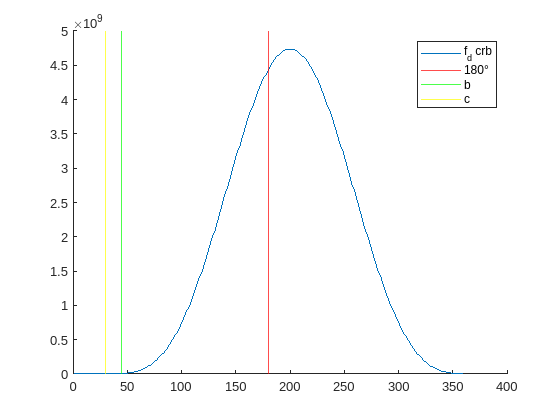

plot(varying_a)
xline(180, 'r')
xline(rad2deg(pi/4),'g')
xline(rad2deg(pi/6), 'y')
legend('f_d crb', '180°', 'b', 'c')

varying_b = zeros(360,1);
for i=1:360
     try
        varying_b(i) = simplify(subs(invFI(1,1), [a,b,c,T,sp], [pi/4,deg2rad(i), pi/6, 0.08e-3, -1]));
     catch ME
        if (strcmp(ME.identifier,'symbolic:kernel:DivisionByZero'))
            disp('division by zero') 
            varying_b(i) = 1e12;
        end
     end
end

division by zero
division by zero


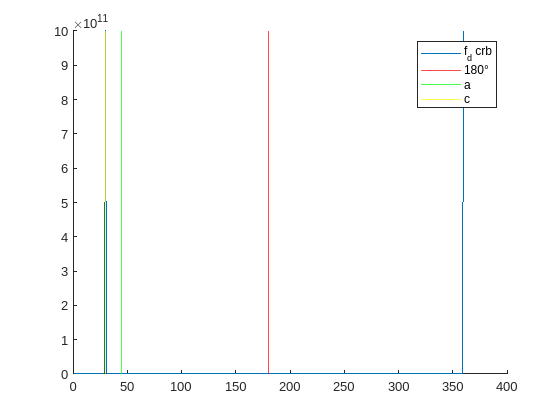

figure
hold on
plot(varying_b)
xline(180,'r')
xline(rad2deg(pi/4),'g')
xline(rad2deg(pi/6), 'y')
legend('f_d crb', '180°', 'a', 'c')

varying_c = zeros(360,1);
for i=1:360
     try
        varying_c(i) = simplify(subs(invFI(1,1), [a,b,c,T,sp], [pi/4, pi/6, deg2rad(i), 0.08e-3, -1]));
     catch ME
        if (strcmp(ME.identifier,'symbolic:kernel:DivisionByZero'))
            disp('division by zero') 
            varying_c(i) = 1e12;
        end
     end
end

division by zero
division by zero


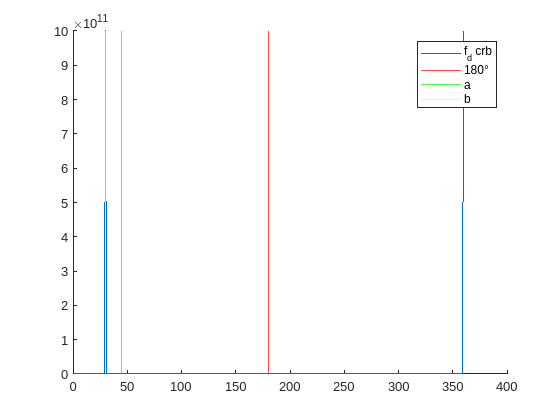

figure
hold on
plot(varying_c)
xline(180,'r')
xline(rad2deg(pi/4),'g')
xline(rad2deg(pi/6), 'y')
legend('f_d crb', '180°', 'a', 'b')

function y1 = f1(fD, v, eta, T, l, x)
y1 = 2*pi*T*(fD+(v/l)*(cos(eta - x) - cos(eta)));
end

function ym = fm(v, eta, T, l, x)
ym = 2*pi*T*(v/l)*(cos(eta - x) - cos(eta));
end

